Task 1: Part 1

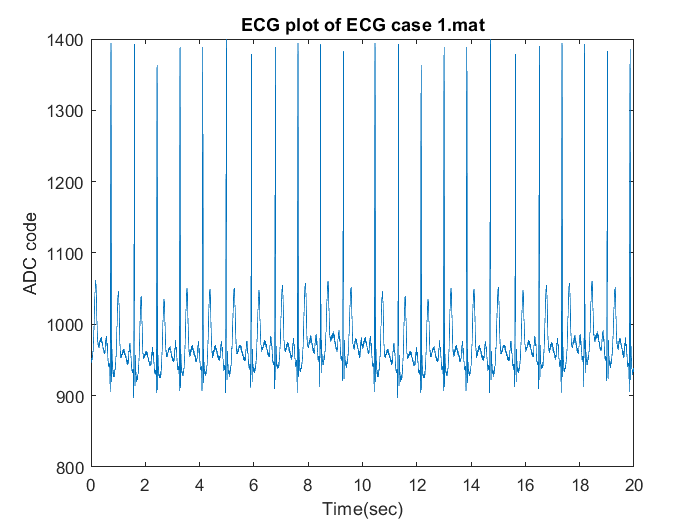

load ("ECG_case_1.mat");
ECG_case1 = ECG;
array_size_ECG1 = length(ECG_case1)/Fs;
interval_ECG1 = array_size_ECG1/length(ECG_case1);
t = 0:interval_ECG1:array_size_ECG1;
t1= t(1:7201);
figure(1)
plot(t1,ECG_case1)
title ("ECG plot of ECG case 1.mat")
xlabel ("Time(sec)")
ylabel ("ADC code")

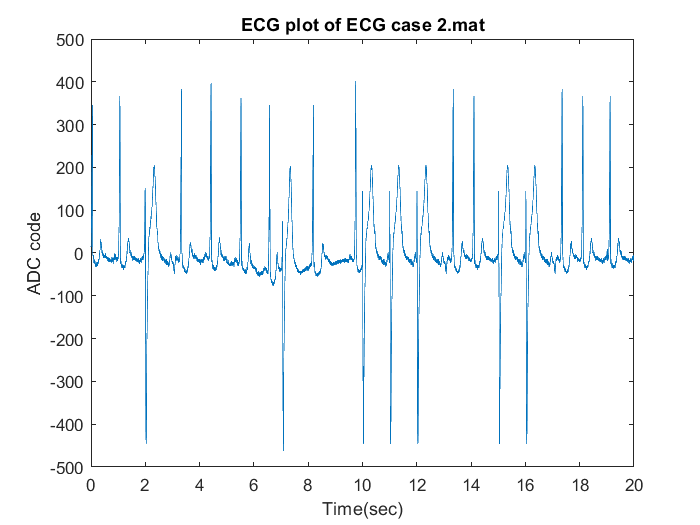


load ("ECG_case_2.mat");
ECG_case2 = ECG;
array_size_ECG2 = length(ECG_case2)/Fs;
interval_ECG2 = array_size_ECG2/length(ECG_case2);
t_prime = 0:interval_ECG2:array_size_ECG2;
t2 = t_prime(1:7200);
figure(2)
plot (t2,ECG_case2)
title ("ECG plot of ECG case 2.mat")
xlabel ("Time(sec)")
ylabel ("ADC code")

Part 2

            1.  cardiac arrhythmia type = PVC

            2.  no. of time specific arrhythmia occur = 0 in ECG case 1, 7 in ECG             case 2

            3.  location in arrhythmia in ECG case 2 = 2.04, 7.07, 10.03, 11.02, 12.03, 15.0, 16.04.

Part 3

There is abnormal heartbeat trend in the graph. It is having a high wave amplitude and short RR interval which indicates that it is a PVC arrhythmia. And in case 2, there is sudden decrease in amplitude.

Task 2

load ECG_case_1.mat
ECG

ECG =          949         949         949         949         949         949         949         949         947         947         947         948         952         952         950         951         950         952         953         955         956         955         955         958         959         962         963         962         962         964         968         974         974         975         977         980         985         991         992         992         997        1000        1006        1012        1015        1017        1021        1024        1030        1036


m = mean(ECG)

m = 976.0726

removed_ECG_1 = ECG -m

removed_ECG_1 =   -27.0726  -27.0726  -27.0726  -27.0726  -27.0726  -27.0726  -27.0726  -27.0726  -29.0726  -29.0726  -29.0726  -28.0726  -24.0726  -24.0726  -26.0726  -25.0726  -26.0726  -24.0726  -23.0726  -21.0726  -20.0726  -21.0726  -21.0726  -18.0726  -17.0726  -14.0726  -13.0726  -14.0726  -14.0726  -12.0726   -8.0726   -2.0726   -2.0726   -1.0726    0.9274    3.9274    8.9274   14.9274   15.9274   15.9274   20.9274   23.9274   29.9274   35.9274   38.9274   40.9274   44.9274   47.9274   53.9274   59.9274


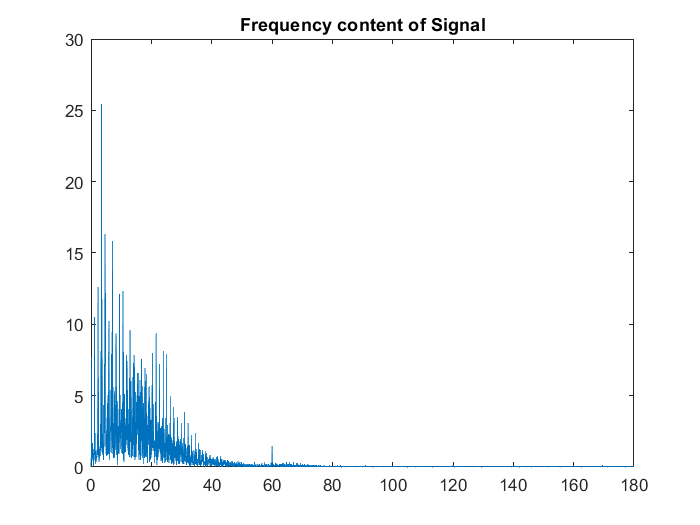


[X,f] = frft(removed_ECG_1, Fs);
plot(f,abs(X))
title("Frequency content of Signal")

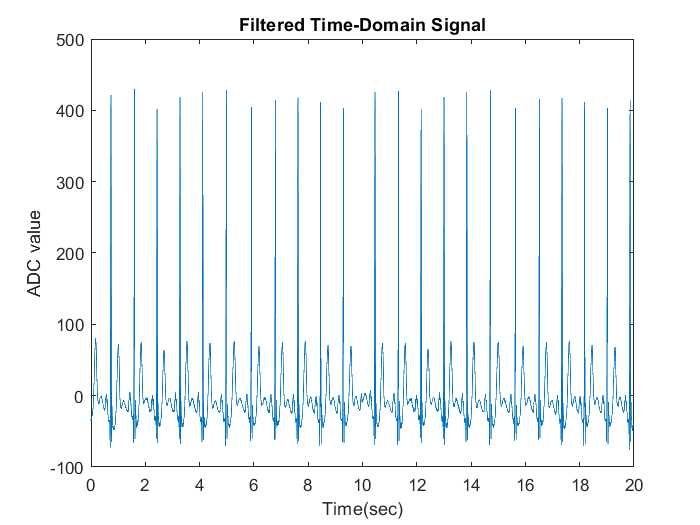


flowcutoff = 0.5;
fupcutoff = 45;
df = f(2)-f(1);
lowcutoffindex = ceil(flowcutoff/df);
upcutoffindex = ceil(fupcutoff/df);

X (1:lowcutoffindex) = 0;
X (upcutoffindex:end) = 0;

[xfiltered, t] = invfrft(X, f, Fs);
plot(t, xfiltered)
xlabel("Time(sec)")
ylabel("ADC value")
title("Filtered Time-Domain Signal")


[Peaks, Locations] = findpeaks(xfiltered,Fs,'MinPeakHeight',350)

Peaks =   421.3226  428.6782  401.3376  418.5146  425.2621  427.4339  403.6569  414.7380  417.9965  410.8701  402.8077  426.1016  426.6661  402.4180  418.1369  425.3554  427.7462  403.2941  415.2525  417.3407  411.5474  402.3624  413.8328


Locations =     0.7361    1.6000    2.4333    3.2778    4.1167    4.9861    5.9111    6.7889    7.6250    8.4556    9.2972   10.4611   11.3250   12.1583   13.0028   13.8417   14.7111   15.6361   16.5139   17.3500   18.1806   19.0222   19.8556



hrv = zeros(1,22);
for i = 1:22
    hrv(i) = Locations(i+1) - Locations(i);
end
hrv_per_minute = hrv/60

hrv_per_minute =     0.0144    0.0139    0.0141    0.0140    0.0145    0.0154    0.0146    0.0139    0.0138    0.0140    0.0194    0.0144    0.0139    0.0141    0.0140    0.0145    0.0154    0.0146    0.0139    0.0138    0.0140    0.0139


bpm  = zeros(1,22);
for n = 1:22
    bpm(n) = 1/hrv_per_minute(n);
end
bpm

bpm =    69.4534   72.0000   71.0526   71.5232   69.0096   64.8649   68.3544   71.7608   72.2408   71.2871   51.5513   69.4534   72.0000   71.0526   71.5232   69.0096   64.8649   68.3544   71.7608   72.2408   71.2871   72.0000


time = linspace(0,20,22)

time =          0    0.9524    1.9048    2.8571    3.8095    4.7619    5.7143    6.6667    7.6190    8.5714    9.5238   10.4762   11.4286   12.3810   13.3333   14.2857   15.2381   16.1905   17.1429   18.0952   19.0476   20.0000


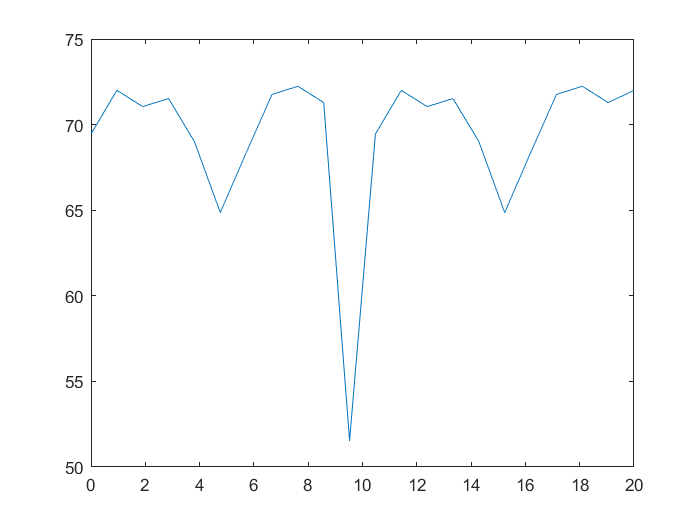

plot(time,bpm)

Task 3

[R, R_locs] = findpeaks(xfiltered, 'MinPeakHeight',350)

R =   421.3226  428.6782  401.3376  418.5146  425.2621  427.4339  403.6569  414.7380  417.9965  410.8701  402.8077  426.1016  426.6661  402.4180  418.1369  425.3554  427.7462  403.2941  415.2525  417.3407  411.5474  402.3624  413.8328


R_locs =          266         577         877        1181        1483        1796        2129        2445        2746        3045        3348        3767        4078        4378        4682        4984        5297        5630        5946        6247        6546        6849        7149


Q = zeros(1, 23)

Q =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


P = zeros(1, 23)

P =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


S = zeros(1, 23)

S =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


T = zeros(1, 23)

T =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Q_locs = zeros(1, 23)

Q_locs =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


P_locs = zeros(1, 23)

P_locs =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


S_locs = zeros(1, 23)

S_locs =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


T_locs = zeros(1, 23)

T_locs =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:23
    [Q(i), Q_locs(i)] = findpeaks(-xfiltered(R_locs(i) - 18: R_locs(i)),"NPeaks",1)
    Q_locs(i) = R_locs(i) - Q_locs(i)
    Q(i) = -1*Q(i)
    
    [P(i), P_locs(i)] = findpeaks(xfiltered(Q_locs(i) - 58: Q_locs(i)),'NPeaks',1)
    P_locs(i) = Q_locs(i) - (58 - P_locs(i))
    
    [S(i), S_locs(i)] = findpeaks(-xfiltered(R_locs(i): R_locs(i) + 25), "NPeaks", 1)
    S_locs(i) = R_locs(i) + S_locs(i)
    S(i) = -1*S(i)
    
    if i == 23
        exceed = abs(length(xfiltered) - (R_locs(i) + 150))
        [T(i), T_locs(i)] = findpeaks(xfiltered(R_locs(i): end), "NPeaks", 1)
        [temp_locs, loc] = findpeaks(xfiltered(1: exceed), "NPeaks", 1, "MinPeakHeight", 50)
        if temp_locs > T(i)
            T(i) = temp_locs
            T_locs(i) = loc
        else
            T_locs(i) = R_locs(i) + T_locs(i)
        end
    else
        [T(i), T_locs(i)] = findpeaks(xfiltered(R_locs(i): R_locs(i) + 150), "NPeaks", 1, "MinPeakHeight", 50)
        T_locs(i) = R_locs(i) + T_locs(i)
    end
end

Q =    72.7671         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Q_locs =      8     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Q_locs =    258     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Q =   -72.7671         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P =     1.5709         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P_locs =      7     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


P_locs =    207     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


S =    64.9055         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


S_locs =      9     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


S_locs =    275     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


S =   -64.9055         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T =    71.2357         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T_locs =     99     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


T_locs =    365     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Q =   -72.7671   66.4930         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Q_locs =    258     8     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Q_locs =    258   569     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Q =   -72.7671  -66.4930         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P =     1.5709    4.8180         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P_locs =    207     8     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


P_locs =    207   519     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


S =   -64.9055   60.7379         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


S_locs =    275     8     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


S_locs =    275   585     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


S =   -64.9055  -60.7379         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T =    71.2357   74.7750         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T_locs =    365    91     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


T_locs =    365   668     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Q =   -72.7671  -66.4930   60.1700         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Q_locs =    258   569     8     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Q_locs =    258   569   869     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Q =   -72.7671  -66.4930  -60.1700         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P =     1.5709    4.8180    0.0199         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P_locs = 1×23
   207   519     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


P_locs = 1×23
   207   519   814     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


S = 1×23
  -64.9055  -60.7379   66.5028         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×23
   275   585     9     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


S_locs = 1×23
   275   585   886     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


S = 1×23
  -64.9055  -60.7379  -66.5028         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T = 1×23
   71.2357   74.7750   64.3020         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×23
   365   668    93     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


T_locs = 1×23
   365   668   970     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Q = 1×23
  -72.7671  -66.4930  -60.1700   60.6567         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Q_locs = 1×23
   258   569   869     9     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Q_locs = 1×23
         258         569         869        1172           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P_locs = 1×23
   207   519   814    11     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


P_locs = 1×23
         207         519         814        1125           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028   67.6376         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×23
   275   585   886     9     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


S_locs = 1×23
         275         585         886        1190           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×23
   365   668   970    94     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


T_locs = 1×23
         365         668         970        1275           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567   65.3189         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Q_locs = 1×23
         258         569         869        1172           9           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Q_locs = 1×23
         258         569         869        1172        1474           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P_locs = 1×23
         207         519         814        1125           5           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


P_locs = 1×23
         207         519         814        1125        1421           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376   61.7335         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×23
         275         585         886        1190           9           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S_locs = 1×23
         275         585         886        1190        1492           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×23
         365         668         970        1275          95           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


T_locs = 1×23
         365         668         970        1275        1578           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189   69.3384         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Q_locs = 1×23
         258         569         869        1172        1474           7           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Q_locs = 1×23
         258         569         869        1172        1474        1789           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P_locs = 1×23
         207         519         814        1125        1421           2           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


P_locs = 1×23
         207         519         814        1125        1421        1733           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335   61.3446         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×23
         275         585         886        1190        1492           9           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S_locs = 1×23
         275         585         886        1190        1492        1805           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×23
         365         668         970        1275        1578         103           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


T_locs = 1×23
         365         668         970        1275        1578        1899           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384   62.7349         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Q_locs = 1×23
         258         569         869        1172        1474        1789           8           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901    2.7560         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P_locs = 1×23
         207         519         814        1125        1421        1733           7           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446   61.2638         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×23
         275         585         886        1190        1492        1805           9           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×23
         365         668         970        1275        1578        1899         101           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349   61.9101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121           8           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901    2.7560    1.9781         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070           9           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638   60.3142         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138           9           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230          94           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101   68.1002         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437           8           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901    2.7560    1.9781    1.6344         0         0         0         0         0         0         0         0         0         0         0         0         0         0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388           9           0           0           0           0           0           0           0           0           0           0           0           0           0           0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142   63.4234         0         0         0         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454           9           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299   76.3771         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539          99           0           0           0           0           0           0           0           0           0           0           0           0           0           0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845           0           0           0           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002   70.2234         0         0         0         0         0         0         0         0         0         0         0         0         0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738           8           0           0           0           0           0           0           0           0           0           0           0           0           0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037           0           0           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234         0         0         0         0         0         0         0         0         0         0         0         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901    2.7560    1.9781    1.6344   -0.5416         0         0         0         0         0         0         0         0         0         0         0         0         0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689           9           0           0           0           0           0           0           0           0           0           0           0           0           0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234   68.2108         0         0         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755           9           0           0           0           0           0           0           0           0           0           0           0           0           0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108         0         0         0         0         0         0         0         0         0         0         0         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299   76.3771   70.6947         0         0         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845         100           0           0           0           0           0           0           0           0           0           0           0           0           0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145           0           0           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234   64.7510         0         0         0         0         0         0         0         0         0         0         0         0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037           8           0           0           0           0           0           0           0           0           0           0           0           0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340           0           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510         0         0         0         0         0         0         0         0         0         0         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901    2.7560    1.9781    1.6344   -0.5416    1.3602         0         0         0         0         0         0         0         0         0         0         0         0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988           9           0           0           0           0           0           0           0           0           0           0           0           0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108   66.9772         0         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054           9           0           0           0           0           0           0           0           0           0           0           0           0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772         0         0         0         0         0         0         0         0         0         0         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299   76.3771   70.6947   69.8538         0         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145         102           0           0           0           0           0           0           0           0           0           0           0           0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450           0           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510   68.2881         0         0         0         0         0         0         0         0         0         0         0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340           8           0           0           0           0           0           0           0           0           0           0           0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881         0         0         0         0         0         0         0         0         0         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901    2.7560    1.9781    1.6344   -0.5416    1.3602    6.8386         0         0         0         0         0         0         0         0         0         0         0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291           5           0           0           0           0           0           0           0           0           0           0           0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772   60.2513         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357           9           0           0           0           0           0           0           0           0           0           0           0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776           0           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513         0         0         0         0         0         0         0         0         0         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299   76.3771   70.6947   69.8538   73.9253         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450          99           0           0           0           0           0           0           0           0           0           0           0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866           0           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881   68.4402         0         0         0         0         0         0         0         0         0         0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759           8           0           0           0           0           0           0           0           0           0           0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402         0         0         0         0         0         0         0         0         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901    2.7560    1.9781    1.6344   -0.5416    1.3602    6.8386    3.4253         0         0         0         0         0         0         0         0         0         0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706           8           0           0           0           0           0           0           0           0           0           0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513   62.8864         0         0         0         0         0         0         0         0         0         0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776           8           0           0           0           0           0           0           0           0           0           0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086           0           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864         0         0         0         0         0         0         0         0         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299   76.3771   70.6947   69.8538   73.9253   73.1825         0         0         0         0         0         0         0         0         0         0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866          91           0           0           0           0           0           0           0           0           0           0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169           0           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402   59.2236         0         0         0         0         0         0         0         0         0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070           8           0           0           0           0           0           0           0           0           0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236         0         0         0         0         0         0         0         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901    2.7560    1.9781    1.6344   -0.5416    1.3602    6.8386    3.4253    0.3379         0         0         0         0         0         0         0         0         0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020           3           0           0           0           0           0           0           0           0           0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864   65.3530         0         0         0         0         0         0         0         0         0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086           9           0           0           0           0           0           0           0           0           0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387           0           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530         0         0         0         0         0         0         0         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299   76.3771   70.6947   69.8538   73.9253   73.1825   65.6006         0         0         0         0         0         0         0         0         0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169          93           0           0           0           0           0           0           0           0           0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471           0           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236   60.9140         0         0         0         0         0         0         0         0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370           9           0           0           0           0           0           0           0           0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370        4673           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236  -60.9140         0         0         0         0         0         0         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901    2.7560    1.9781    1.6344   -0.5416    1.3602    6.8386    3.4253    0.3379    4.9187         0         0         0         0         0         0         0         0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315          11           0           0           0           0           0           0           0           0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315        4626           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530   68.0899         0         0         0         0         0         0         0         0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387           9           0           0           0           0           0           0           0           0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691           0           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899         0         0         0         0         0         0         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299   76.3771   70.6947   69.8538   73.9253   73.1825   65.6006   76.2442         0         0         0         0         0         0         0         0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471          94           0           0           0           0           0           0           0           0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776           0           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236  -60.9140   65.4642         0         0         0         0         0         0         0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370        4673           9           0           0           0           0           0           0           0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370        4673        4975           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236  -60.9140  -65.4642         0         0         0         0         0         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901    2.7560    1.9781    1.6344   -0.5416    1.3602    6.8386    3.4253    0.3379    4.9187   -1.4362         0         0         0         0         0         0         0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315        4626           5           0           0           0           0           0           0           0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315        4626        4922           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899   61.5700         0         0         0         0         0         0         0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691           9           0           0           0           0           0           0           0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691        4993           0           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899  -61.5700         0         0         0         0         0         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299   76.3771   70.6947   69.8538   73.9253   73.1825   65.6006   76.2442   74.9638         0         0         0         0         0         0         0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776          95           0           0           0           0           0           0           0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776        5079           0           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236  -60.9140  -65.4642   69.1235         0         0         0         0         0         0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370        4673        4975           7           0           0           0           0           0           0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370        4673        4975        5290           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236  -60.9140  -65.4642  -69.1235         0         0         0         0         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901    2.7560    1.9781    1.6344   -0.5416    1.3602    6.8386    3.4253    0.3379    4.9187   -1.4362    2.3366         0         0         0         0         0         0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315        4626        4922           2           0           0           0           0           0           0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315        4626        4922        5234           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899  -61.5700   61.0933         0         0         0         0         0         0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691        4993           9           0           0           0           0           0           0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691        4993        5306           0           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899  -61.5700  -61.0933         0         0         0         0         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299   76.3771   70.6947   69.8538   73.9253   73.1825   65.6006   76.2442   74.9638   74.6213         0         0         0         0         0         0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776        5079         103           0           0           0           0           0           0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776        5079        5400           0           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236  -60.9140  -65.4642  -69.1235   63.0431         0         0         0         0         0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370        4673        4975        5290           8           0           0           0           0           0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370        4673        4975        5290        5622           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236  -60.9140  -65.4642  -69.1235  -63.0431         0         0         0         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901    2.7560    1.9781    1.6344   -0.5416    1.3602    6.8386    3.4253    0.3379    4.9187   -1.4362    2.3366    2.2281         0         0         0         0         0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315        4626        4922        5234           7           0           0           0           0           0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315        4626        4922        5234        5571           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899  -61.5700  -61.0933   61.5745         0         0         0         0         0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691        4993        5306           9           0           0           0           0           0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691        4993        5306        5639           0           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899  -61.5700  -61.0933  -61.5745         0         0         0         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299   76.3771   70.6947   69.8538   73.9253   73.1825   65.6006   76.2442   74.9638   74.6213   69.9008         0         0         0         0         0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776        5079        5400         101           0           0           0           0           0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776        5079        5400        5731           0           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236  -60.9140  -65.4642  -69.1235  -63.0431   61.4832         0         0         0         0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370        4673        4975        5290        5622           8           0           0           0           0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370        4673        4975        5290        5622        5938           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236  -60.9140  -65.4642  -69.1235  -63.0431  -61.4832         0         0         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901    2.7560    1.9781    1.6344   -0.5416    1.3602    6.8386    3.4253    0.3379    4.9187   -1.4362    2.3366    2.2281    2.6400         0         0         0         0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315        4626        4922        5234        5571           9           0           0           0           0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315        4626        4922        5234        5571        5889           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899  -61.5700  -61.0933  -61.5745   59.8403         0         0         0         0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691        4993        5306        5639           9           0           0           0           0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691        4993        5306        5639        5955           0           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899  -61.5700  -61.0933  -61.5745  -59.8403         0         0         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299   76.3771   70.6947   69.8538   73.9253   73.1825   65.6006   76.2442   74.9638   74.6213   69.9008   74.2632         0         0         0         0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776        5079        5400        5731          94           0           0           0           0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776        5079        5400        5731        6040           0           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236  -60.9140  -65.4642  -69.1235  -63.0431  -61.4832   68.6946         0         0         0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370        4673        4975        5290        5622        5938           8           0           0           0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370        4673        4975        5290        5622        5938        6239           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236  -60.9140  -65.4642  -69.1235  -63.0431  -61.4832  -68.6946         0         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901    2.7560    1.9781    1.6344   -0.5416    1.3602    6.8386    3.4253    0.3379    4.9187   -1.4362    2.3366    2.2281    2.6400    0.9354         0         0         0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315        4626        4922        5234        5571        5889           9           0           0           0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315        4626        4922        5234        5571        5889        6190           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899  -61.5700  -61.0933  -61.5745  -59.8403   64.0588         0         0         0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691        4993        5306        5639        5955           9           0           0           0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691        4993        5306        5639        5955        6256           0           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899  -61.5700  -61.0933  -61.5745  -59.8403  -64.0588         0         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299   76.3771   70.6947   69.8538   73.9253   73.1825   65.6006   76.2442   74.9638   74.6213   69.9008   74.2632   76.2288         0         0         0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776        5079        5400        5731        6040          99           0           0           0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776        5079        5400        5731        6040        6346           0           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236  -60.9140  -65.4642  -69.1235  -63.0431  -61.4832  -68.6946   69.7107         0         0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370        4673        4975        5290        5622        5938        6239           8           0           0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370        4673        4975        5290        5622        5938        6239        6538           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236  -60.9140  -65.4642  -69.1235  -63.0431  -61.4832  -68.6946  -69.7107         0         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901    2.7560    1.9781    1.6344   -0.5416    1.3602    6.8386    3.4253    0.3379    4.9187   -1.4362    2.3366    2.2281    2.6400    0.9354   -0.0949         0         0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315        4626        4922        5234        5571        5889        6190           9           0           0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315        4626        4922        5234        5571        5889        6190        6489           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899  -61.5700  -61.0933  -61.5745  -59.8403  -64.0588   67.5276         0         0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691        4993        5306        5639        5955        6256           9           0           0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691        4993        5306        5639        5955        6256        6555           0           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899  -61.5700  -61.0933  -61.5745  -59.8403  -64.0588  -67.5276         0         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299   76.3771   70.6947   69.8538   73.9253   73.1825   65.6006   76.2442   74.9638   74.6213   69.9008   74.2632   76.2288   71.2241         0         0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776        5079        5400        5731        6040        6346         100           0           0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776        5079        5400        5731        6040        6346        6646           0           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236  -60.9140  -65.4642  -69.1235  -63.0431  -61.4832  -68.6946  -69.7107   65.0812         0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370        4673        4975        5290        5622        5938        6239        6538           8           0


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370        4673        4975        5290        5622        5938        6239        6538        6841           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236  -60.9140  -65.4642  -69.1235  -63.0431  -61.4832  -68.6946  -69.7107  -65.0812         0


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901    2.7560    1.9781    1.6344   -0.5416    1.3602    6.8386    3.4253    0.3379    4.9187   -1.4362    2.3366    2.2281    2.6400    0.9354   -0.0949    1.2101         0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315        4626        4922        5234        5571        5889        6190        6489           9           0


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315        4626        4922        5234        5571        5889        6190        6489        6792           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899  -61.5700  -61.0933  -61.5745  -59.8403  -64.0588  -67.5276   67.4748         0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691        4993        5306        5639        5955        6256        6555           9           0


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691        4993        5306        5639        5955        6256        6555        6858           0


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899  -61.5700  -61.0933  -61.5745  -59.8403  -64.0588  -67.5276  -67.4748         0


T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299   76.3771   70.6947   69.8538   73.9253   73.1825   65.6006   76.2442   74.9638   74.6213   69.9008   74.2632   76.2288   71.2241   68.9131         0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776        5079        5400        5731        6040        6346        6646         101           0


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776        5079        5400        5731        6040        6346        6646        6950           0


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236  -60.9140  -65.4642  -69.1235  -63.0431  -61.4832  -68.6946  -69.7107  -65.0812   75.6198


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370        4673        4975        5290        5622        5938        6239        6538        6841           8


Q_locs = 1×23
         258         569         869        1172        1474        1789        2121        2437        2738        3037        3340        3759        4070        4370        4673        4975        5290        5622        5938        6239        6538        6841        7141


Q = 1×23
  -72.7671  -66.4930  -60.1700  -60.6567  -65.3189  -69.3384  -62.7349  -61.9101  -68.1002  -70.2234  -64.7510  -68.2881  -68.4402  -59.2236  -60.9140  -65.4642  -69.1235  -63.0431  -61.4832  -68.6946  -69.7107  -65.0812  -75.6198


P = 1×23
    1.5709    4.8180    0.0199    4.6449   -1.0139    1.5901    2.7560    1.9781    1.6344   -0.5416    1.3602    6.8386    3.4253    0.3379    4.9187   -1.4362    2.3366    2.2281    2.6400    0.9354   -0.0949    1.2101   -0.5575


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315        4626        4922        5234        5571        5889        6190        6489        6792           4


P_locs = 1×23
         207         519         814        1125        1421        1733        2070        2388        2689        2988        3291        3706        4020        4315        4626        4922        5234        5571        5889        6190        6489        6792        7087


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899  -61.5700  -61.0933  -61.5745  -59.8403  -64.0588  -67.5276  -67.4748   64.6351


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691        4993        5306        5639        5955        6256        6555        6858           9


S_locs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691        4993        5306        5639        5955        6256        6555        6858        7158


S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899  -61.5700  -61.0933  -61.5745  -59.8403  -64.0588  -67.5276  -67.4748  -64.6351


exceed = 98

T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299   76.3771   70.6947   69.8538   73.9253   73.1825   65.6006   76.2442   74.9638   74.6213   69.9008   74.2632   76.2288   71.2241   68.9131   -9.5402


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776        5079        5400        5731        6040        6346        6646        6950          14


temp_locs = 80.0226

loc = 64

T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299   76.3771   70.6947   69.8538   73.9253   73.1825   65.6006   76.2442   74.9638   74.6213   69.9008   74.2632   76.2288   71.2241   68.9131   80.0226


T_locs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776        5079        5400        5731        6040        6346        6646        6950          64


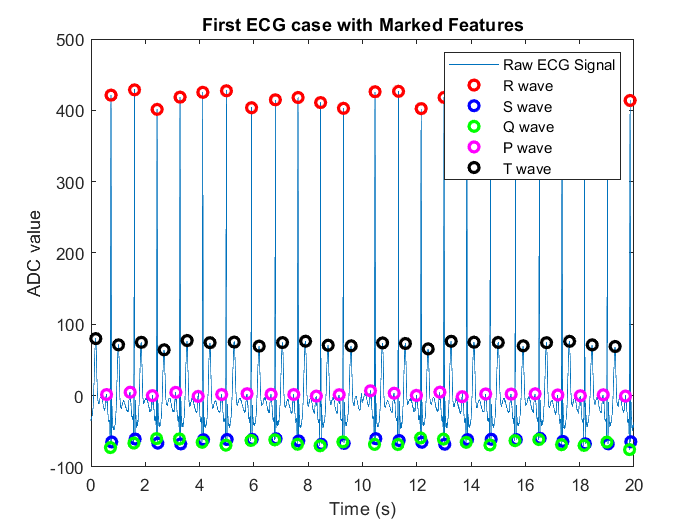

plot(t, xfiltered, '-', 'DisplayName', 'Raw ECG Signal')
hold on
plot(R_locs ./ Fs, R, 'ro', 'linewidth', 2, 'DisplayName', 'R wave')
plot(S_locs ./ Fs, S, 'bo', 'linewidth', 2, 'DisplayName', 'S wave')
plot(Q_locs ./ Fs, Q, 'go', 'linewidth', 2, 'DisplayName', 'Q wave')
plot(P_locs ./ Fs, P, 'mo', 'linewidth', 2, 'DisplayName', 'P wave')
plot(T_locs ./ Fs, T, 'ko', 'linewidth', 2, 'DisplayName', 'T wave')
title("First ECG case with Marked Features")
xlabel("Time (s)")
ylabel("ADC value")
legend
hold off

ECG1_R = R

ECG1_R = 1×23
  421.3226  428.6782  401.3376  418.5146  425.2621  427.4339  403.6569  414.7380  417.9965  410.8701  402.8077  426.1016  426.6661  402.4180  418.1369  425.3554  427.7462  403.2941  415.2525  417.3407  411.5474  402.3624  413.8328


ECG1_Rlocs = R_locs

ECG1_Rlocs = 1×23
         266         577         877        1181        1483        1796        2129        2445        2746        3045        3348        3767        4078        4378        4682        4984        5297        5630        5946        6247        6546        6849        7149


ECG1_T = T

ECG1_T = 1×23
   71.2357   74.7750   64.3020   77.2766   74.3238   75.1542   69.4471   74.4299   76.3771   70.6947   69.8538   73.9253   73.1825   65.6006   76.2442   74.9638   74.6213   69.9008   74.2632   76.2288   71.2241   68.9131   80.0226


ECG1_S = S

ECG1_S = 1×23
  -64.9055  -60.7379  -66.5028  -67.6376  -61.7335  -61.3446  -61.2638  -60.3142  -63.4234  -68.2108  -66.9772  -60.2513  -62.8864  -65.3530  -68.0899  -61.5700  -61.0933  -61.5745  -59.8403  -64.0588  -67.5276  -67.4748  -64.6351


ECG1_Tlocs = T_locs

ECG1_Tlocs = 1×23
         365         668         970        1275        1578        1899        2230        2539        2845        3145        3450        3866        4169        4471        4776        5079        5400        5731        6040        6346        6646        6950          64


ECG1_Slocs = S_locs

ECG1_Slocs = 1×23
         275         585         886        1190        1492        1805        2138        2454        2755        3054        3357        3776        4086        4387        4691        4993        5306        5639        5955        6256        6555        6858        7158


Task 4

Applying same code to case 2

m = mean(ECG_case2)

m = -2.4206

removed_ECG_2 = ECG_case2 -m

removed_ECG_2 = 1×7200
   15.4206   19.4206   28.4206   40.4206   47.4206   56.4206   61.4206   71.4206   91.4206  115.4206  141.4206  162.4206  183.4206  204.4206  232.4206  272.4206  313.4206  341.4206  346.4206  325.4206  269.4206  190.4206  112.4206   52.4206   16.4206    1.4206   -4.5794   -1.5794   -3.5794   -4.5794



[X,f] = frft(removed_ECG_2, Fs)

X = 1×3601
  -0.0000 + 0.0000i   2.9876 + 8.6174i   2.1387 - 7.4295i  -6.1836 + 2.0836i  -0.4319 - 2.6745i   3.7590 + 1.6924i  -0.9775 + 1.1101i  -1.8194 + 5.4360i   4.9496 - 1.8262i  -0.7364 - 2.9086i   2.0494 - 2.6982i  -0.2589 - 1.2103i  -4.6178 - 2.9604i  -0.1602 + 5.9286i   0.4674 + 6.2999i  -9.9616 + 1.7458i   8.4564 - 6.7153i   9.1121 + 4.1653i   7.3706 - 4.0866i   3.1765 + 6.8778i -24.6738 -23.1557i  15.2521 - 1.3090i  -1.3335 + 2.8247i   7.1436 + 4.7926i  -4.7447 +19.1536i   3.5842 -13.0364i   0.8033 - 3.6280i  12.3149 - 0.3155i  -8.2103 - 7.8465i  -1.5651 + 0.9598i


f = 1×3601
         0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500



flowcutoff = 0.5

flowcutoff = 0.5000

fupcutoff = 45

fupcutoff = 45

df = f(2)-f(1)

df = 0.0500

lowcutoffindex = ceil(flowcutoff/df)

lowcutoffindex = 10

upcutoffindex = ceil(fupcutoff/df)

upcutoffindex = 900


X (1:lowcutoffindex) = 0

X = 1×3601
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0494 - 2.6982i  -0.2589 - 1.2103i  -4.6178 - 2.9604i  -0.1602 + 5.9286i   0.4674 + 6.2999i  -9.9616 + 1.7458i   8.4564 - 6.7153i   9.1121 + 4.1653i   7.3706 - 4.0866i   3.1765 + 6.8778i -24.6738 -23.1557i  15.2521 - 1.3090i  -1.3335 + 2.8247i   7.1436 + 4.7926i  -4.7447 +19.1536i   3.5842 -13.0364i   0.8033 - 3.6280i  12.3149 - 0.3155i  -8.2103 - 7.8465i  -1.5651 + 0.9598i


X (upcutoffindex:end) = 0

X = 1×3601
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   2.0494 - 2.6982i  -0.2589 - 1.2103i  -4.6178 - 2.9604i  -0.1602 + 5.9286i   0.4674 + 6.2999i  -9.9616 + 1.7458i   8.4564 - 6.7153i   9.1121 + 4.1653i   7.3706 - 4.0866i   3.1765 + 6.8778i -24.6738 -23.1557i  15.2521 - 1.3090i  -1.3335 + 2.8247i   7.1436 + 4.7926i  -4.7447 +19.1536i   3.5842 -13.0364i   0.8033 - 3.6280i  12.3149 - 0.3155i  -8.2103 - 7.8465i  -1.5651 + 0.9598i



[xfiltered2, t2] = invfrft(X, f, Fs)

xfiltered2 = 1×7200
   10.2734   19.7600   27.1382   32.6952   38.3381   46.5637   59.0633   75.7676   94.9345  114.3069  132.7231  151.2122  172.7762  200.7181  236.1894  276.1903  313.2107  337.0339  338.2048  311.8001  259.8557  191.2969  119.2622   56.8538   13.0247   -9.7656  -15.3124  -11.1694   -5.1555   -2.4322


t2 = 1×7200
         0    0.0028    0.0056    0.0083    0.0111    0.0139    0.0167    0.0194    0.0222    0.0250    0.0278    0.0306    0.0333    0.0361    0.0389    0.0417    0.0444    0.0472    0.0500    0.0528    0.0556    0.0583    0.0611    0.0639    0.0667    0.0694    0.0722    0.0750    0.0778    0.0806




[R,R_locs] = findpeaks(xfiltered2, 'MinPeakDistance', 80, 'MinPeakHeight', 50)

R = 1×27
  338.2048  366.4297  143.9494  191.9936  378.7639  396.7518  368.4616  376.2780   98.5042  212.2039  359.8155  403.0283  100.9475  192.9166   94.7607  192.1175   93.8142  192.2348  375.8440  367.9245  108.7346  194.7634   89.7585  190.0759  378.3755  362.4885  360.5396


R_locs = 1×27
          19         384         719         838        1200        1592        1990        2370        2540        2642        2949        3511        3602        3722        3963        4083        4324        4440        4804        5079        5407        5523        5768        5884        6248        6523        6884


insert_index = 1;

% temp_locs = R_locs(R < 250)
% temp = R(R < 250)
% R_locs = R_locs(R > 250)
% R = R(R > 250)
lenR = length(R_locs)

lenR = 27

i = 1

i = 1

while  i <= lenR
    if R(i) < 250
        if ~mod(insert_index, 2)
            R(i) = []
            R_locs(i) = []
            i = i - 1
        end
        insert_index = insert_index + 1
    end
    lenR = length(R_locs)
    i = i + 1
end

lenR = 27

i = 2

lenR = 27

i = 3

insert_index = 2

lenR = 27

i = 4

R = 1×26
  338.2048  366.4297  143.9494  378.7639  396.7518  368.4616  376.2780   98.5042  212.2039  359.8155  403.0283  100.9475  192.9166   94.7607  192.1175   93.8142  192.2348  375.8440  367.9245  108.7346  194.7634   89.7585  190.0759  378.3755  362.4885  360.5396


R_locs = 1×26
          19         384         719        1200        1592        1990        2370        2540        2642        2949        3511        3602        3722        3963        4083        4324        4440        4804        5079        5407        5523        5768        5884        6248        6523        6884


i = 3

insert_index = 3

lenR = 26

i = 4

lenR = 26

i = 5

lenR = 26

i = 6

lenR = 26

i = 7

lenR = 26

i = 8

insert_index = 4

lenR = 26

i = 9

R = 1×25
  338.2048  366.4297  143.9494  378.7639  396.7518  368.4616  376.2780   98.5042  359.8155  403.0283  100.9475  192.9166   94.7607  192.1175   93.8142  192.2348  375.8440  367.9245  108.7346  194.7634   89.7585  190.0759  378.3755  362.4885  360.5396


R_locs = 1×25
          19         384         719        1200        1592        1990        2370        2540        2949        3511        3602        3722        3963        4083        4324        4440        4804        5079        5407        5523        5768        5884        6248        6523        6884


i = 8

insert_index = 5

lenR = 25

i = 9

lenR = 25

i = 10

lenR = 25

i = 11

insert_index = 6

lenR = 25

i = 12

R = 1×24
  338.2048  366.4297  143.9494  378.7639  396.7518  368.4616  376.2780   98.5042  359.8155  403.0283  100.9475   94.7607  192.1175   93.8142  192.2348  375.8440  367.9245  108.7346  194.7634   89.7585  190.0759  378.3755  362.4885  360.5396


R_locs = 1×24
          19         384         719        1200        1592        1990        2370        2540        2949        3511        3602        3963        4083        4324        4440        4804        5079        5407        5523        5768        5884        6248        6523        6884


i = 11

insert_index = 7

lenR = 24

i = 12

insert_index = 8

lenR = 24

i = 13

R = 1×23
  338.2048  366.4297  143.9494  378.7639  396.7518  368.4616  376.2780   98.5042  359.8155  403.0283  100.9475   94.7607   93.8142  192.2348  375.8440  367.9245  108.7346  194.7634   89.7585  190.0759  378.3755  362.4885  360.5396


R_locs = 1×23
          19         384         719        1200        1592        1990        2370        2540        2949        3511        3602        3963        4324        4440        4804        5079        5407        5523        5768        5884        6248        6523        6884


i = 12

insert_index = 9

lenR = 23

i = 13

insert_index = 10

lenR = 23

i = 14

R = 1×22
  338.2048  366.4297  143.9494  378.7639  396.7518  368.4616  376.2780   98.5042  359.8155  403.0283  100.9475   94.7607   93.8142  375.8440  367.9245  108.7346  194.7634   89.7585  190.0759  378.3755  362.4885  360.5396


R_locs = 1×22
          19         384         719        1200        1592        1990        2370        2540        2949        3511        3602        3963        4324        4804        5079        5407        5523        5768        5884        6248        6523        6884


i = 13

insert_index = 11

lenR = 22

i = 14

lenR = 22

i = 15

lenR = 22

i = 16

insert_index = 12

lenR = 22

i = 17

R = 1×21
  338.2048  366.4297  143.9494  378.7639  396.7518  368.4616  376.2780   98.5042  359.8155  403.0283  100.9475   94.7607   93.8142  375.8440  367.9245  108.7346   89.7585  190.0759  378.3755  362.4885  360.5396


R_locs = 1×21
          19         384         719        1200        1592        1990        2370        2540        2949        3511        3602        3963        4324        4804        5079        5407        5768        5884        6248        6523        6884


i = 16

insert_index = 13

lenR = 21

i = 17

insert_index = 14

lenR = 21

i = 18

R = 1×20
  338.2048  366.4297  143.9494  378.7639  396.7518  368.4616  376.2780   98.5042  359.8155  403.0283  100.9475   94.7607   93.8142  375.8440  367.9245  108.7346   89.7585  378.3755  362.4885  360.5396


R_locs = 1×20
          19         384         719        1200        1592        1990        2370        2540        2949        3511        3602        3963        4324        4804        5079        5407        5768        6248        6523        6884


i = 17

insert_index = 15

lenR = 20

i = 18

lenR = 20

i = 19

lenR = 20

i = 20

lenR = 20

i = 21


T = zeros(1,length(R_locs))

T = 1×20
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


T_locs = T

T_locs = 1×20
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


S = T

S = 1×20
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


S_locs = T

S_locs = 1×20
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


T = 1×20
   27.9909         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×20
    78     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


T_locs = 1×20
   132     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


S = 1×20
  -31.6771         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×20
    56     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


T = 1×20
   27.9909   39.1877         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×20
   132    78     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


T_locs = 1×20
   132   497     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


S = 1×20
  -31.6771  -28.5511         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×20
    74    49     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


T = 1×20
   27.9909   39.1877  191.9936         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×20
   132   497    84     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


T_locs = 1×20
   132   497   838     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


S = 1×20
  -31.6771  -28.5511 -456.1049         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×20
    74   432    14     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


T = 1×20
   27.9909   39.1877  191.9936   32.6364         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×20
   132   497   838    88     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


T_locs = 1×20
         132         497         838        1323           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×20
  -31.6771  -28.5511 -456.1049  -41.1216         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×20
    74   432   732    64     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


T = 1×20
   27.9909   39.1877  191.9936   32.6364   32.7206         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×20
         132         497         838        1323          75           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


T_locs = 1×20
         132         497         838        1323        1702           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×20
  -31.6771  -28.5511 -456.1049  -41.1216  -39.4891         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×20
          74         432         732        1263          64           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0


T = 1×20
   27.9909   39.1877  191.9936   32.6364   32.7206   45.2340         0         0         0         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×20
         132         497         838        1323        1702          78           0           0           0           0           0           0           0           0           0           0           0           0           0           0


T_locs = 1×20
         132         497         838        1323        1702        2103           0           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×20
  -31.6771  -28.5511 -456.1049  -41.1216  -39.4891  -26.4891         0         0         0         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×20
          74         432         732        1263        1655          62           0           0           0           0           0           0           0           0           0           0           0           0           0           0


T = 1×20
   27.9909   39.1877  191.9936   32.6364   32.7206   45.2340   26.3679         0         0         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×20
         132         497         838        1323        1702        2103          63           0           0           0           0           0           0           0           0           0           0           0           0           0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468           0           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×20
  -31.6771  -28.5511 -456.1049  -41.1216  -39.4891  -26.4891  -42.6345         0         0         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×20
          74         432         732        1263        1655        2051          48           0           0           0           0           0           0           0           0           0           0           0           0           0


T = 1×20
   27.9909   39.1877  191.9936   32.6364   32.7206   45.2340   26.3679  212.2039         0         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468          67           0           0           0           0           0           0           0           0           0           0           0           0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642           0           0           0           0           0           0           0           0           0           0           0           0


S = 1×20
  -31.6771  -28.5511 -456.1049  -41.1216  -39.4891  -26.4891  -42.6345 -451.5934         0         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×20
          74         432         732        1263        1655        2051        2417          11           0           0           0           0           0           0           0           0           0           0           0           0


T = 1×20
   27.9909   39.1877  191.9936   32.6364   32.7206   45.2340   26.3679  212.2039   42.7759         0         0         0         0         0         0         0         0         0         0         0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642          89           0           0           0           0           0           0           0           0           0           0           0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0           0           0           0           0           0           0           0           0           0           0


S = 1×20
  -31.6771  -28.5511 -456.1049  -41.1216  -39.4891  -26.4891  -42.6345 -451.5934  -34.6156         0         0         0         0         0         0         0         0         0         0         0


S_locs = 1×20
          74         432         732        1263        1655        2051        2417        2550          41           0           0           0           0           0           0           0           0           0           0           0


S = 1×20
  -31.6771  -28.5511 -456.1049  -41.1216  -39.4891  -26.4891  -42.6345 -451.5934  -34.6156  -50.4751         0         0         0         0         0         0         0         0         0         0


S_locs = 1×20
          74         432         732        1263        1655        2051        2417        2550        2989          56           0           0           0           0           0           0           0           0           0           0


T = 1×20
   27.9909   39.1877  191.9936   32.6364   32.7206   45.2340   26.3679  212.2039   42.7759         0  192.9166         0         0         0         0         0         0         0         0         0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0          85           0           0           0           0           0           0           0           0           0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722           0           0           0           0           0           0           0           0           0


S = 1×20
  -31.6771  -28.5511 -456.1049  -41.1216  -39.4891  -26.4891  -42.6345 -451.5934  -34.6156  -50.4751 -450.1020         0         0         0         0         0         0         0         0         0


S_locs = 1×20
          74         432         732        1263        1655        2051        2417        2550        2989        3566          12           0           0           0           0           0           0           0           0           0


T = 1×20
   27.9909   39.1877  191.9936   32.6364   32.7206   45.2340   26.3679  212.2039   42.7759         0  192.9166  192.1175         0         0         0         0         0         0         0         0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722          85           0           0           0           0           0           0           0           0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722        4083           0           0           0           0           0           0           0           0


S = 1×20
  -31.6771  -28.5511 -456.1049  -41.1216  -39.4891  -26.4891  -42.6345 -451.5934  -34.6156  -50.4751 -450.1020 -454.7961         0         0         0         0         0         0         0         0


S_locs = 1×20
          74         432         732        1263        1655        2051        2417        2550        2989        3566        3613          12           0           0           0           0           0           0           0           0


T = 1×20
   27.9909   39.1877  191.9936   32.6364   32.7206   45.2340   26.3679  212.2039   42.7759         0  192.9166  192.1175  192.2348         0         0         0         0         0         0         0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722        4083          81           0           0           0           0           0           0           0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722        4083        4440           0           0           0           0           0           0           0


S = 1×20
  -31.6771  -28.5511 -456.1049  -41.1216  -39.4891  -26.4891  -42.6345 -451.5934  -34.6156  -50.4751 -450.1020 -454.7961 -455.1560         0         0         0         0         0         0         0


S_locs = 1×20
          74         432         732        1263        1655        2051        2417        2550        2989        3566        3613        3974          12           0           0           0           0           0           0           0


T = 1×20
   27.9909   39.1877  191.9936   32.6364   32.7206   45.2340   26.3679  212.2039   42.7759         0  192.9166  192.1175  192.2348   28.1035         0         0         0         0         0         0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722        4083        4440          88           0           0           0           0           0           0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722        4083        4440        4927           0           0           0           0           0           0


S = 1×20
  -31.6771  -28.5511 -456.1049  -41.1216  -39.4891  -26.4891  -42.6345 -451.5934  -34.6156  -50.4751 -450.1020 -454.7961 -455.1560  -46.7586         0         0         0         0         0         0


S_locs = 1×20
          74         432         732        1263        1655        2051        2417        2550        2989        3566        3613        3974        4335          64           0           0           0           0           0           0


T = 1×20
   27.9909   39.1877  191.9936   32.6364   32.7206   45.2340   26.3679  212.2039   42.7759         0  192.9166  192.1175  192.2348   28.1035   40.8178         0         0         0         0         0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722        4083        4440        4927          78           0           0           0           0           0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722        4083        4440        4927        5192           0           0           0           0           0


S = 1×20
  -31.6771  -28.5511 -456.1049  -41.1216  -39.4891  -26.4891  -42.6345 -451.5934  -34.6156  -50.4751 -450.1020 -454.7961 -455.1560  -46.7586  -27.1893         0         0         0         0         0


S_locs = 1×20
          74         432         732        1263        1655        2051        2417        2550        2989        3566        3613        3974        4335        4867          49           0           0           0           0           0


T = 1×20
   27.9909   39.1877  191.9936   32.6364   32.7206   45.2340   26.3679  212.2039   42.7759         0  192.9166  192.1175  192.2348   28.1035   40.8178  194.7634         0         0         0         0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722        4083        4440        4927        5192          81           0           0           0           0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722        4083        4440        4927        5192        5523           0           0           0           0


S = 1×20
  -31.6771  -28.5511 -456.1049  -41.1216  -39.4891  -26.4891  -42.6345 -451.5934  -34.6156  -50.4751 -450.1020 -454.7961 -455.1560  -46.7586  -27.1893 -446.4678         0         0         0         0


S_locs = 1×20
          74         432         732        1263        1655        2051        2417        2550        2989        3566        3613        3974        4335        4867        5127          12           0           0           0           0


T = 1×20
   27.9909   39.1877  191.9936   32.6364   32.7206   45.2340   26.3679  212.2039   42.7759         0  192.9166  192.1175  192.2348   28.1035   40.8178  194.7634  190.0759         0         0         0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722        4083        4440        4927        5192        5523          81           0           0           0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722        4083        4440        4927        5192        5523        5884           0           0           0


S = 1×20
  -31.6771  -28.5511 -456.1049  -41.1216  -39.4891  -26.4891  -42.6345 -451.5934  -34.6156  -50.4751 -450.1020 -454.7961 -455.1560  -46.7586  -27.1893 -446.4678 -459.1424         0         0         0


S_locs = 1×20
          74         432         732        1263        1655        2051        2417        2550        2989        3566        3613        3974        4335        4867        5127        5418          12           0           0           0


T = 1×20
   27.9909   39.1877  191.9936   32.6364   32.7206   45.2340   26.3679  212.2039   42.7759         0  192.9166  192.1175  192.2348   28.1035   40.8178  194.7634  190.0759   27.1403         0         0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722        4083        4440        4927        5192        5523        5884          88           0           0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722        4083        4440        4927        5192        5523        5884        6371           0           0


S = 1×20
  -31.6771  -28.5511 -456.1049  -41.1216  -39.4891  -26.4891  -42.6345 -451.5934  -34.6156  -50.4751 -450.1020 -454.7961 -455.1560  -46.7586  -27.1893 -446.4678 -459.1424  -45.6453         0         0


S_locs = 1×20
          74         432         732        1263        1655        2051        2417        2550        2989        3566        3613        3974        4335        4867        5127        5418        5779          64           0           0


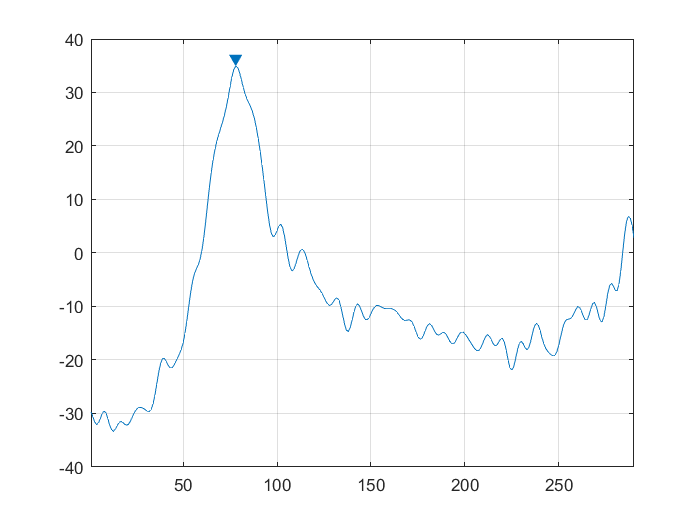

T = 1×20
   27.9909   39.1877  191.9936   32.6364   32.7206   45.2340   26.3679  212.2039   42.7759         0  192.9166  192.1175  192.2348   28.1035   40.8178  194.7634  190.0759   27.1403   34.9307         0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722        4083        4440        4927        5192        5523        5884        6371          78           0


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722        4083        4440        4927        5192        5523        5884        6371        6636           0


S = 1×20
  -31.6771  -28.5511 -456.1049  -41.1216  -39.4891  -26.4891  -42.6345 -451.5934  -34.6156  -50.4751 -450.1020 -454.7961 -455.1560  -46.7586  -27.1893 -446.4678 -459.1424  -45.6453  -33.2859         0


S_locs = 1×20
          74         432         732        1263        1655        2051        2417        2550        2989        3566        3613        3974        4335        4867        5127        5418        5779        6311          49           0


T = 1×20
   27.9909   39.1877  191.9936   32.6364   32.7206   45.2340   26.3679  212.2039   42.7759         0  192.9166  192.1175  192.2348   28.1035   40.8178  194.7634  190.0759   27.1403   34.9307   33.2921


T_locs = 1×20
         132         497         838        1323        1702        2103        2468        2642        3073           0        3722        4083        4440        4927        5192        5523        5884        6371        6636          79


S = 1×20
  -31.6771  -28.5511 -456.1049  -41.1216  -39.4891  -26.4891  -42.6345 -451.5934  -34.6156  -50.4751 -450.1020 -454.7961 -455.1560  -46.7586  -27.1893 -446.4678 -459.1424  -45.6453  -33.2859  -34.9248


S_locs = 1×20
          74         432         732        1263        1655        2051        2417        2550        2989        3566        3613        3974        4335        4867        5127        5418        5779        6311        6571          49



for i=1:length(R_locs)
    if i<length(R_locs)
        if ~isempty(findpeaks(xfiltered2(R_locs(i) + 36 :R_locs(i+1) - 36), "NPeaks",1, "MinPeakProminence", 20))
            findpeaks(xfiltered2(R_locs(i) + 36:R_locs(i+1) - 36), "NPeaks",1, "MinPeakProminence", 20)
            [T(i), T_locs(i)] = findpeaks(xfiltered2(R_locs(i) + 36: R_locs(i + 1) - 36), "NPeaks",1, "MinPeakProminence", 20)
            T_locs(i) = R_locs(i) + 36 - 1 + T_locs(i)
        end
        
        [S(i),S_locs(i)] = min(xfiltered2(R_locs(i):min(R_locs(i)+ 144,R_locs(i+1))))
        S_locs(i) = R_locs(i) - 1 + S_locs(i);
    else
        [T(i),T_locs(i)] = findpeaks(xfiltered2(R_locs(i) + 36:end), "NPeaks", 1, "MinPeakProminence", 20)
        T_locs(i) = R_locs(i) + 36 - 1 + T_locs(i);
        [S(i),S_locs(i)] = min(xfiltered2(R_locs(i):end))
        S_locs(i) = R_locs(i) - 1 + S_locs(i);
    end
end

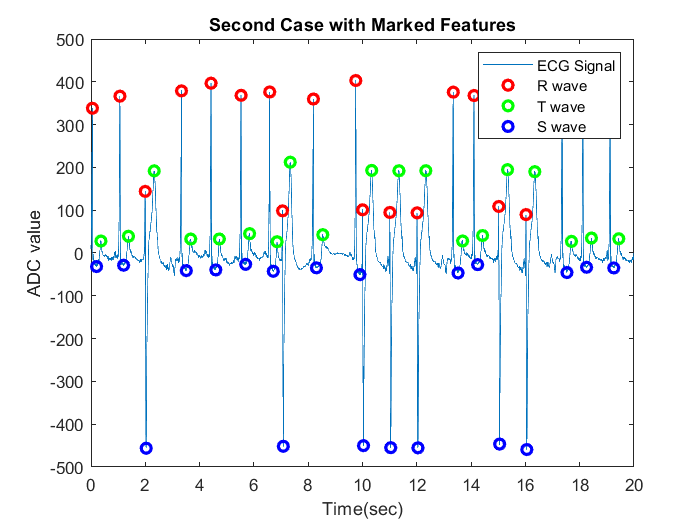

plot(t2,xfiltered2,'-', "DisplayName", "ECG Signal")
hold on
plot(R_locs ./ Fs, R, 'ro', "DisplayName", "R wave", 'linewidth', 2)
plot(T_locs(T ~= 0) ./ Fs, T(T ~= 0), 'go', "DisplayName", "T wave", 'linewidth', 2)
plot(S_locs ./ Fs, S, 'bo', "DisplayName", "S wave", 'linewidth', 2)
title("Second Case with Marked Features")
xlabel("Time(sec)")
ylabel("ADC value")
legend
hold off

Finding HRV

hrv = zeros(1,22);
for i = 1:length(R_locs) - 1
    hrv(i) = R_locs(i+1) - R_locs(i);
    hrv(i) = hrv(i) / Fs
end

hrv = 1×22
    1.0139         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


hrv = 1×22
    1.0139    0.9306         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


hrv = 1×22
    1.0139    0.9306    1.3361         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


hrv = 1×22
    1.0139    0.9306    1.3361    1.0889         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


hrv = 1×22
    1.0139    0.9306    1.3361    1.0889    1.1056         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


hrv = 1×22
    1.0139    0.9306    1.3361    1.0889    1.1056    1.0556         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


hrv = 1×22
    1.0139    0.9306    1.3361    1.0889    1.1056    1.0556    0.4722         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


hrv = 1×22
    1.0139    0.9306    1.3361    1.0889    1.1056    1.0556    0.4722    1.1361         0         0         0         0         0         0         0         0         0         0         0         0         0         0


hrv = 1×22
    1.0139    0.9306    1.3361    1.0889    1.1056    1.0556    0.4722    1.1361    1.5611         0         0         0         0         0         0         0         0         0         0         0         0         0


hrv = 1×22
    1.0139    0.9306    1.3361    1.0889    1.1056    1.0556    0.4722    1.1361    1.5611    0.2528         0         0         0         0         0         0         0         0         0         0         0         0


hrv = 1×22
    1.0139    0.9306    1.3361    1.0889    1.1056    1.0556    0.4722    1.1361    1.5611    0.2528    1.0028         0         0         0         0         0         0         0         0         0         0         0


hrv = 1×22
    1.0139    0.9306    1.3361    1.0889    1.1056    1.0556    0.4722    1.1361    1.5611    0.2528    1.0028    1.0028         0         0         0         0         0         0         0         0         0         0


hrv = 1×22
    1.0139    0.9306    1.3361    1.0889    1.1056    1.0556    0.4722    1.1361    1.5611    0.2528    1.0028    1.0028    1.3333         0         0         0         0         0         0         0         0         0


hrv = 1×22
    1.0139    0.9306    1.3361    1.0889    1.1056    1.0556    0.4722    1.1361    1.5611    0.2528    1.0028    1.0028    1.3333    0.7639         0         0         0         0         0         0         0         0


hrv = 1×22
    1.0139    0.9306    1.3361    1.0889    1.1056    1.0556    0.4722    1.1361    1.5611    0.2528    1.0028    1.0028    1.3333    0.7639    0.9111         0         0         0         0         0         0         0


hrv = 1×22
    1.0139    0.9306    1.3361    1.0889    1.1056    1.0556    0.4722    1.1361    1.5611    0.2528    1.0028    1.0028    1.3333    0.7639    0.9111    1.0028         0         0         0         0         0         0


hrv = 1×22
    1.0139    0.9306    1.3361    1.0889    1.1056    1.0556    0.4722    1.1361    1.5611    0.2528    1.0028    1.0028    1.3333    0.7639    0.9111    1.0028    1.3333         0         0         0         0         0


hrv = 1×22
    1.0139    0.9306    1.3361    1.0889    1.1056    1.0556    0.4722    1.1361    1.5611    0.2528    1.0028    1.0028    1.3333    0.7639    0.9111    1.0028    1.3333    0.7639         0         0         0         0


hrv = 1×22
    1.0139    0.9306    1.3361    1.0889    1.1056    1.0556    0.4722    1.1361    1.5611    0.2528    1.0028    1.0028    1.3333    0.7639    0.9111    1.0028    1.3333    0.7639    1.0028         0         0         0


hrv_per_minute = hrv/60

hrv_per_minute = 1×22
    0.0169    0.0155    0.0223    0.0181    0.0184    0.0176    0.0079    0.0189    0.0260    0.0042    0.0167    0.0167    0.0222    0.0127    0.0152    0.0167    0.0222    0.0127    0.0167         0         0         0


bpm  = zeros(1,22);
for n = 1:22
    bpm(n) = 1/hrv_per_minute(n);
end
bpm

bpm = 1×22
   59.1781   64.4776   44.9064   55.1020   54.2714   56.8421  127.0588   52.8117   38.4342  237.3626   59.8338   59.8338   45.0000   78.5455   65.8537   59.8338   45.0000   78.5455   59.8338       Inf       Inf       Inf


time = linspace(0,20,22)

time = 1×22
         0    0.9524    1.9048    2.8571    3.8095    4.7619    5.7143    6.6667    7.6190    8.5714    9.5238   10.4762   11.4286   12.3810   13.3333   14.2857   15.2381   16.1905   17.1429   18.0952   19.0476   20.0000


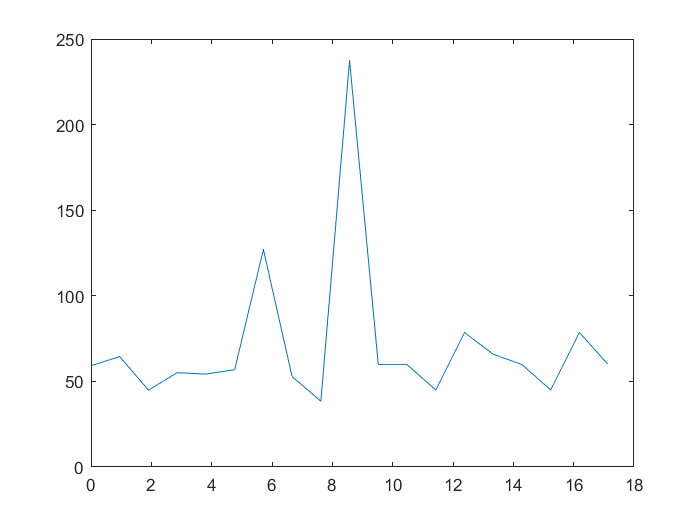

plot(time,bpm)

Task 5 Applying to ECG 2

X = [0,0];
[~,min_idx] = min([R_locs(1),T_locs(1),S_locs(1)]);
if min_idx==3
    R_locs = [0, R_locs];
    X(1)=1;
elseif min_idx==2
    T_locs = T_locs(2:end);
end

[~,min_idx] = min([R_locs(1),T_locs(1),S_locs(1)]);
if min_idx==3
    ECG1_Rlocs = [0, ECG1_Rlocs];
    X(2)= 1;
elseif min_idx==2
    T_locs = T_locs(2:end);
end

[~,max_idx] = max([R_locs(end),T_locs(end),S_locs(end)]);
if max_idx==3
    R_locs = R_locs(1:end-1);
    S_locs = S_locs(1:end-1);
    X(1)=1;
elseif max_idx==1
    R_locs = R_locs(1:end-1);
end

[~,max_idx] = max([R_locs(end), T_locs(end),S_locs(end)]);
if max_idx==3
    R_locs = R_locs(1:end-1);
    S_locs = S_locs(1:end-1);
    X(1)= 1;
elseif max_idx==1
    R_locs = R_locs(1:end-1);
end


ECG = [R_locs, T_locs, S_locs ; R_locs, T_locs, S_locs, zeros(1,3*abs(length(T_locs)-length(T_locs)))];
ECG_peakT = [T;T,zeros(1,abs(length(T)-length(T)))];
for i=1:2
    no_arrhythmia=true;  
    consec = 0;
    temp = ECG(i,:);
    temp = temp(temp>0);
    num = length(temp)/3;
    for j = 1:num
        short_RR = false;
        long_ST= false;
        high_T = T(T > 100)
    if ~isempty(high_T)
     high_T = true
    end
        end
        if j>1 + X(i)
            if (temp(j)-temp(j-1)<0.6*Fs) 
                short_RR = true;
            end
        end
        if temp(floor(num+j))-temp(floor(2*num+j))>0.28*Fs
            long_ST=true;
        end
        if (high_T && short_RR || high_T && long_ST || long_ST && short_RR) 
            consec=consec+1;
            display("PVC is detected at" +temp(num+j)/Fs+ "seconds for ECG" +i)
            no_arrhythmia = false;
        else
            consec = 0;
        end
        if consec==3 
            display("VT is detected at" +temp(num+j)/Fs+ "seconds for ECG" +i)
        end
    end

high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


high_T = 1×7
  191.9936  212.2039  192.9166  192.1175  192.2348  194.7634  190.0759


high_T = logical
   1


    if (no_arrhythmia) 
        display("No arrhythmia detected" + i)
    end

    "No arrhythmia detected2"



Applying to ECG1

   clear high_T
   clear short_RR
   clear long_ST
    X = [0,0];
[~,min_idx] = min([ECG1_Rlocs(1),ECG1_Tlocs(1),ECG1_Slocs(1)]);
if min_idx==3
    ECG1_Rlocs = [0, ECG1_Rlocs];
    X(1)=1;
elseif min_idx==2
    ECG1_Tlocs = ECG1_Tlocs(2:end);
end

[~,min_idx] = min([ECG1_Rlocs(1),ECG1_Tlocs(1),ECG1_Slocs(1)]);
if min_idx==3
    ECG1_Rlocs = [0, ECG1_Rlocs];
    X(2)= 1;
elseif min_idx==2
    ECG1_Tlocs = ECG1_Tlocs(2:end);
end

[~,max_idx] = max([ECG1_Rlocs(end),ECG1_Tlocs(end),ECG1_Slocs(end)]);
if max_idx==3
    ECG1_Rlocs = ECG1_Rlocs(1:end-1);
    ECG1_Slocs = ECG1_Slocs(1:end-1);
    X(1)=1;
elseif max_idx==1
    ECG1_Rlocs = ECG1_Rlocs(1:end-1);
end

[~,max_idx] = max([ECG1_Rlocs(end), ECG1_Tlocs(end),ECG1_Slocs(end)]);
if max_idx==3
    ECG1_Rlocs = ECG1_Rlocs(1:end-1);
    ECG1_Slocs = ECG1_Slocs(1:end-1);
    X(1)= 1;
elseif max_idx==1
    ECG1_Rlocs = ECG1_Rlocs(1:end-1);
end


ECG = [ECG1_Rlocs, ECG1_Tlocs, ECG1_Slocs ; ECG1_Rlocs, ECG1_Tlocs, ECG1_Slocs, zeros(1,3*abs(length(ECG1_Tlocs)-length(ECG1_Tlocs)))];
ECG_peakT = [T;T,zeros(1,abs(length(T)-length(T)))];
for i=1:2
    no_arrhythmia=true;  
    consec = 0;
    temp = ECG(i,:);
    temp = temp(temp>0);
    num = length(temp)/3;
    for j = 1:num
        short_RR = false;
        long_ST= false;
        high_T = ECG1_T(ECG1_T > 100)
    if ~isempty(high_T)
     high_T = true
    end
        end
        if j>1 + X(i)
            if (temp(j)-temp(j-1)<0.6*Fs) 
                short_RR = true;
            end
        end
        if temp(floor(num+j))-temp(floor(2*num+j))>0.28*Fs
            long_ST=true;
        end
        if (high_T && short_RR || high_T && long_ST || long_ST && short_RR) 
            consec=consec+1;
            display("PVC is detected at" +temp(num+j)/Fs+ "seconds for ECG" +i)
            no_arrhythmia = false;
        else
            consec = 0;
        end
        if consec==3 
            display("VT is detected at" +temp(num+j)/Fs+ "seconds for ECG" +i)
        end
    end


high_T =

  1×0 empty double row vector


high_T =

  1×0 empty double row vector


high_T =

  1×0 empty double row vector


high_T =

  1×0 empty double row vector


high_T =

  1×0 empty double row vector


high_T =

  1×0 empty double row vector


high_T =

  1×0 empty double row vector


high_T =

  1×0 empty double row vector


high_T =

  1×0 empty double row vector


high_T =

  1×0 empty 

Operands to the || and && operators must be convertible to logical scalar values.

    if (no_arrhythmia) 
        display("No arrhythmia detected" + i)
    end